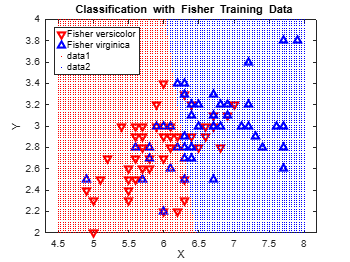

%Zadanie 1
%W przykładzie 1 zamienić funkcję klasyfikującą na liniową 'linear'. Zauważyć różnice w działaniu
%klasyfikatora dla różnych funkcji 'quadratic', 'linear'.
load fisheriris 

SL = meas(51:end,1); 
SW = meas(51:end,2); 
group = species(51:end); 

h1 = gscatter(SL,SW,group,'rb','v^',[],'off'); 
set(h1,'LineWidth',2) 
legend('Fisher versicolor','Fisher virginica','Location','NW') 

% klasyfikacja
[X,Y] = meshgrid(linspace(4.5,8),linspace(2,4)); 
X = X(:); Y = Y(:); 


[C,err,P,logp,coeff] = classify([X Y],[SL SW], group,'linear');  % zmiana na 'linear'

% rysunek

hold on; 
gscatter(X,Y,C,'rb','.',1,'off'); 
title('{ Classification with Fisher Training Data}')

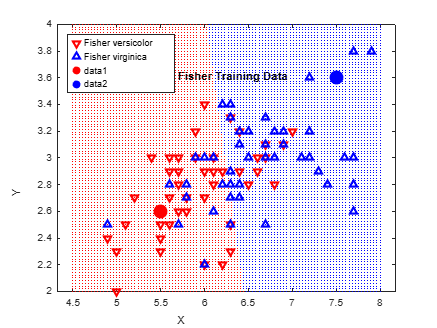

%%Zadanie 2
%W przykładzie 1 sprawdzić do której kategorii (klasy) należą następujące punkty A(5.5, 2.6), B(7.5,
%3.6), C(5, 3.8). Co stanie się, gdy 'quadratic' zamienimy na 'linear' i jakie wyniki wówczas
%otrzymamy (zmienna C)? Co otrzymujemy w zmiennej P?

load fisheriris 

SL = meas(51:end,1); 
SW = meas(51:end,2); 
group = species(51:end); 

h1 = gscatter(SL,SW,group,'rb','v^',[],'off'); 
set(h1,'LineWidth',2) 
legend('Fisher versicolor','Fisher virginica','Location','NW') 

% klasyfikacja
X = [5.5; 7.5; 5]; 
Y = [2.6; 3.6; 3.8]; 

%[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'quadratic'); 
[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'linear'); 

% rysunek

hold on; 
gscatter(X, Y, C, 'rb', '.', [40], 'off'); 
title({'Classification with Fisher Training Data'})

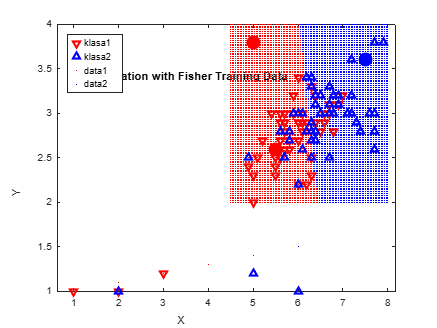

%%Zadanie 3
% Na podstawie przykładu 1 zastąpić zbiór trenujący wektorami SL=[1; 2; 3; 2; 5; 6], SW =[1; 1; 1; 1.2;
% 1; 1], group = ['klasa1'; 'klasa1'; 'klasa1'; 'klasa2'; 'klasa2'; 'klasa2']. Następnie sklasyfikować metodą
% LDA punkty o współrzędnych X=[1; 2; 3; 4; 5; 6], Y =[1; 1.1; 1.2; 1.3; 1.4; 1.5]. Zobaczyć wyniki w
% zmiennej C. Co się stanie, gdy SW =[1; 1; 1; 1; 1; 1] i z jakiego powodu taka sytuacja wystąpiła? 
% Gdy SW = [1; 1; 1; 1; 1; 1] to dostaniemy jeden punkt przez, który klasyfikator nie wie jak poprowadzić linię prostą.

% Dane
SL = [1; 2; 3; 2; 5; 6]; 
SW = [1; 1; 1.2; 1; 1.2; 1]; 
group = {'klasa1'; 'klasa1'; 'klasa1'; 'klasa2'; 'klasa2'; 'klasa2'}; 

h1 = gscatter(SL, SW, group, 'rb', 'v^', [], 'off'); 
set(h1, 'LineWidth', 2) 
legend('klasa1', 'klasa2', 'Location', 'NW') 

% Klasyfikacja
X = [1; 2; 3; 4; 5; 6]; 
Y = [1; 1.1; 1.2; 1.3; 1.4; 1.5]; 
X = X(:); 
Y = Y(:); 

%[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'quadratic'); 
[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'linear'); 

% Rysunek

hold on; 
gscatter(X, Y, C, 'rb', '.', 1, 'off'); 
title({'Classification with Fisher Training Data'})

%%Zadanie 4
% Napisać program z 3 klasami i klasyfikujący wektory w przestrzeni dwuwymiarowej. 

SL=[1; 2; 3; 2; 5; 6;1;2;3];
SW =[1; 1; 1; 1.2; 1; 1; 2;1.8;2];
group = ['klasa1'; 'klasa1'; 'klasa1'; 'klasa2'; 'klasa2'; 'klasa2'; 'klasa3'; 'klasa3'; 'klasa3' ];

h1 = gscatter(SL,SW,group,'rbg','v',[],'off')

h1 =   3x1 Line array:

  Line    (data3)
  Line    (data4)
  Line    (data5)


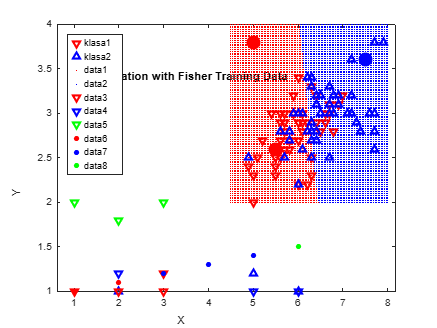

set(h1,'LineWidth',2)

%klasyfikacja
X=[1; 2; 3; 4; 5; 6];
Y =[1; 1.1; 1.2; 1.3; 1.4; 1.5];
%[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'quadratic'); 
[C, err, P, logp, coeff] = classify([X Y], [SL SW], group, 'linear'); 

% Rysunek

hold on; 
gscatter(X, Y, C, 'rbg', '.', [], 'off'); 
title({'Classification with Fisher Training Data'})

%%Zadanie 5
%Napisać program, który będzie klasyfikować metodą LDA w przestrzeni jednowymiarowej
%odpowiednio następujące wartośc
%Zaobserwować wyniki w zmiennej C. 

SL=[1; 2; 3; 4; 5; 6;7;8;9];
group = ['klasa1'; 'klasa1'; 'klasa1'; 'klasa2'; 'klasa2'; 'klasa2'; 'klasa3'; 'klasa3'; 'klasa3'];

%klasyfikacja
X=[0.4; 2; 3.51; 3.6; 5; 6; 6.3; 6.4;6.51]; 
%[C, err, P, logp, coeff] = classify(X SL, group, 'quadratic'); 
[C, err, P, logp, coeff] = classify(X, SL, group, 'linear'); 

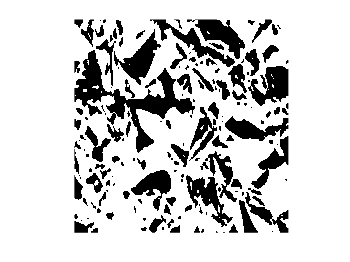

%%Zadanie 6
% Napisać program, który będzie identyfikować zdjęcia silver_4.tif i aluminium_4.tif. Do
% tworzenia wzorców zastosować zdjęcia silver_1.tif, silver_2.tif, silver_3.tif,
% aluminium_1.tif, aluminium_2.tif, aluminium_3.tif. Do klasyfikacji zastosować
% metodę LDA

%**************tworzenie wzorców do rozpoznawania**************
[L1]= imread('silver_1.tif');
L1=rgb2gray(L1);
L2a=L1>210;
figure, imshow(L2a);

Sil_1=sum(sum(L2a))

Sil_1 = 31656

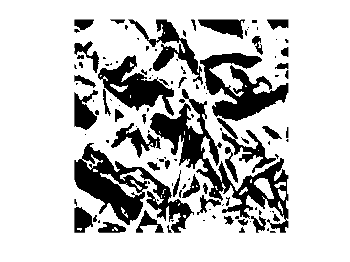


[L1]= imread('silver_2.tif');
L1=rgb2gray(L1);
L2a=L1>210;
figure, imshow(L2a);

Sil_2=sum(sum(L2a))

Sil_2 = 28305

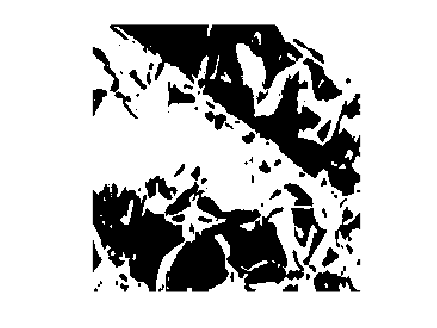


[Z1]= imread('silver_3.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Sil_3=sum(sum(Z2a))

Sil_3 = 26945

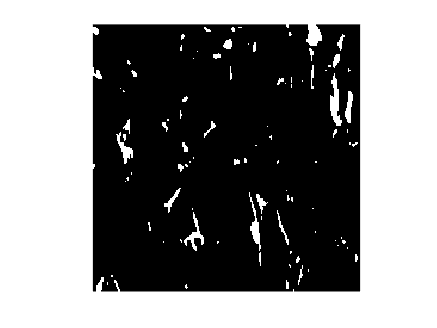


[Z1]= imread('aluminium_1.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Alu_1=sum(sum(Z2a))

Alu_1 = 2084

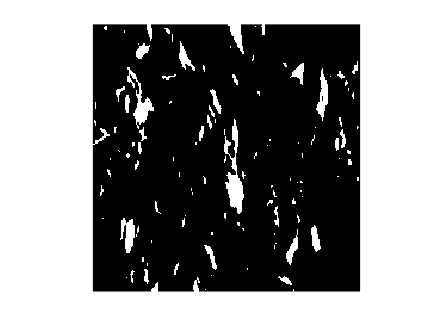


[Z1]= imread('aluminium_2.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Alu_2=sum(sum(Z2a))

Alu_2 = 3321

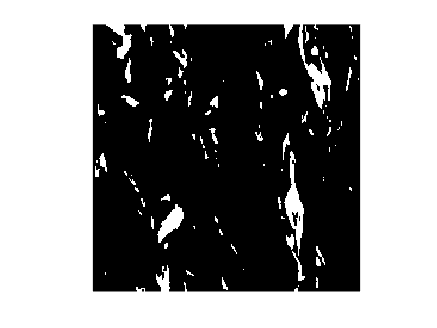


[Z1]= imread('aluminium_3.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Alu_3=sum(sum(Z2a))

Alu_3 = 3348

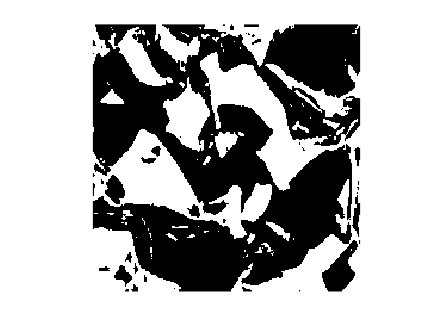

%***************identyfikacja******************
[Z1]= imread('silver_4.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Sil_4=sum(sum(Z2a))

Sil_4 = 19292

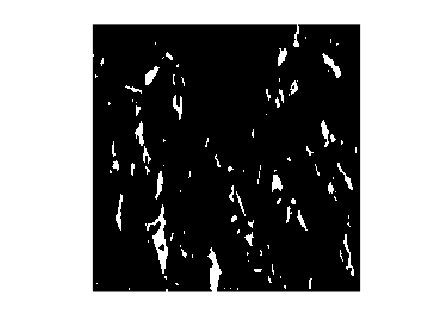


[Z1]= imread('aluminium_4.tif');
Z1=rgb2gray(Z1);
Z2a=Z1>210;
figure, imshow(Z2a);

Alu_4=sum(sum(Z2a))

Alu_4 = 2556


SL= [Sil_1; Sil_2; Sil_3; Alu_1; Alu_2; Alu_3];
group =['klasa1';'klasa1';'klasa1';'klasa2';'klasa2';'klasa2'];
X=[Sil_4; Alu_4];

%[C, err, P, logp, coeff] = classify(X SL, group, 'quadratic'); 
[C, err, P, logp, coeff] = classify(X, SL, group, 'linear'); 

%%Zadanie 7
% Proszę wykonać klasyfikację metodą LDA dla dwóch klas „zdrowy” i „dwa_prety”. Bardzo proszę
% zastosować pliki txt (sygnały przyśpieszeń/drgań) do testowania: zdrowy_5.txt,
% dwa_prety_5.txt.
% Pliki zdrowy_1.txt, zdrowy_2.txt, zdrowy_3.txt, zdrowy_4.txt,
% dwa_prety_1.txt, dwa_prety_2.txt, dwa_prety_3.txt, dwa_prety_4.txt użyć do
% tworzenia wzorców.
% Do ekstrakcji cech proszę zastosować sumę wartości przyśpieszeń

Zd1 = load('zdrowy1.txt');
Zd1 = sum(Zd1);

Zd2 = load('zdrowy2.txt');
Zd2 = sum(Zd2);

Zd3 = load('zdrowy3.txt');
Zd3 = sum(Zd3);

Zd4 = load('zdrowy4.txt');
Zd4 = sum(Zd4);

Zd5 = load('zdrowy5.txt');
Zd5 = sum(Zd5);

Dp1 = load('dwa_prety_1.txt');
Dp1 = sum(Dp1);

Dp2 = load('dwa_prety_2.txt');
Dp2 = sum(Dp2);

Dp3 = load('dwa_prety_3.txt');
Dp3 = sum(Dp3);

Dp4 = load('dwa_prety_4.txt');
Dp4 = sum(Dp4);

Dp5 = load('dwa_prety_5.txt');
Dp5 = sum(Dp5);

SL = [Zd1; Zd2; Zd3; Zd4; Dp1; Dp2; Dp3; Dp4];
group = ['klasa1';'klasa1';'klasa1';'klasa1';'klasa2';'klasa2';'klasa2';'klasa2';]

group = 8x6 char array
    'klasa1'
    'klasa1'
    'klasa1'
    'klasa1'
    'klasa2'
    'klasa2'
    'klasa2'
    'klasa2'



X=[Zd5;Dp5]

X =   119.6000
  146.9100


[C, err, P, logp, coeff] = classify(X, SL, group, 'linear'); 